load('models.mat');

test_data = readtable('test_desc.csv');
categories = ["speed", "speed", "speed", "speed", "speed", "speed", "end", "speed", ...
    "speed", "pass", "pass", "tri", "sq", "ceda", "stop", "emptyC", "speed", ...
    "direcPro", "tri", "tri", "tri", "tri", "tri", "tri", "tri", "tri", "triS", ...
    "tri", "tri", "tri", "tri", "tri", "end", "direc", "direc", "direc", ...
    "direc", "direc", "direc", "direc", "direc", "end", "end"];

[categories, gNames, gL] = grp2idx(categories);

test_data.GeneralSign = arrayfun(@(x) categories(x+1), test_data.Sign);

[label, score] = modelGeneral.predictFcn(test_data);

confMatGeneral = confusionmat(test_data.GeneralSign, label);


sum(test_data.GeneralSign == label)/size(label,1)

ans = 0.8836

confMat = confusionmat(expectedLabels, predictedLabels);
sum(expectedLabels == predictedLabels)/size(expectedLabels,1)

ans = 0.5529

hog_test = readmatrix('test_hog.csv');



gNames(1)

ans = 1×1 cell array
    {'speed'}


[expected, label] = labelHOGtest(modelRedC, hog_test, [0:5, 7,8, 16]);
confMatRedC = confusionmat(expected, label);
accuracyRedC = sum(expected == label)/size(label,1)

accuracyRedC = 0.5855


gNames(2)

ans = 1×1 cell array
    {'end'}


[expected, label] = labelHOGtest(modelCircleEnd, hog_test, [6,32,41,42]);
confMatWhiteC = confusionmat(expected, label);
accuracyWhiteC = sum(expected == label)/size(label,1)

accuracyWhiteC = 0.6296

gNames(4)

ans = 1×1 cell array
    {'tri'}


[expected, label] = labelHOGtest(modelTriangle, hog_test, [11,18:31]);
confMatTri = confusionmat(expected, label);
accuracyTri = sum(expected == label)/size(label,1)

accuracyTri = 0.7379

gNames(11)

ans = 1×1 cell array
    {'direc'}


[expected, label] = labelHOGtest(modelBlueC, hog_test, [33:40]);
confMatBlueC = confusionmat(expected, label);
accuracyBlueC = sum(expected == label)/size(label,1)

accuracyBlueC = 0.9308

% for i = 1:length(label)
% 
% return
% 
% disp(fullFileName)
% 
% I = imread(fullFileName);
% I = preprocess(I);
% [mask, colors] = maskFinder(I);
% trainingFeatures(k, :) = hogDesc(mask, colors.(C));

 [mask, colors] = maskFinder(I);
features = hogDesc(mask, colors.black);
features

features = 1×900 single row vector
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.7071         0         0         0         0         0         0         0    0.7071         0         0         0         0         0         0         0         0         0    0.0247         0         0         0    0.0092


size(hg)

ans =    450   901


I = imread('../images/Test/00012/00012_00004/00010.png');
[final, mid] = labelSignal(I)

    12



final = 12

mid = "sq"

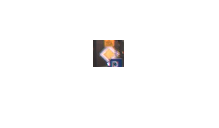


imshow(I)


I = preprocess(I);

desc = newDescriptors(I);
desc = struct2table(desc, 'AsArray', true);

[label, score] = modelGeneral.predictFcn(desc);

label = string(gNames(label))

label = "sq"


done = true;
color = "black";

if label == "speed"
    done = false;
    model = modelRedC;
elseif label == "end"
    done = false;
    model = modelCircleEnd;
elseif label == "pass"
    % TODO
    finalLabel = 9;
elseif label == "tri"
    done = false;
    model = modelTriangle;
elseif label == "sq"
    finalLabel = 12;
elseif label == "ceda"
    finalLabel = 13;
elseif label == "stop"
    finalLabel = 14;
elseif label == "emptyC"
    finalLabel = 15;
elseif label == "direcPro"
    finalLabel = 17;
elseif label == "triS"
    finalLabel = 26;
elseif label == "direc"
    done = false;
    model = modelBlueC;
    color = "white";
else
    finalLabel = 404;
    warning("404 - Not Found")
    return
end

if done
    disp(finalLabel)
    return
end

    12




[mask, colors] = maskFinder(I);
features = hogDesc(mask, colors.(color));

finalLabel = model.predictFcn(features)

testPattern = fullfile('../images/Test/**', '*.png');
[pred, expected] = labelTests(testPattern);

/home/leix/Documents/UPC/VC/vc-traffic-sign-recognition/images/Test/00000/00000_00000/00000.png


Unable to resolve the name modelGeneral.predictFcn.

Error in labelSignal (line 7)
    label = modelGeneral.predictFcn(desc);

Error in labelTests (line 18)
        predictedLabels(k) = labelSignal(I);


sum(pred == expected)/size(pred, 1)

% https://www.programmersought.com/article/62055892576/
labels = data(:,end);

train_x=[];
train_y=[];
test_x=[];
test_y=[];

for label=1:length(unique(labels))
    cate = find(labels==label);
    half = int32(length(cate)*0.1);
    train = cate(randperm(length(cate),half)); %Under the current class, the row of the extracted training set
    test = setdiff(cate,train);% Under the current class, the rest is the row of the test set
    train_x = [train_x;data(train,1:end-1)];
    train_y = [train_y;labels(train)];
    test_x = [test_x;data(test,1:end-1)];
    test_y = [test_y;labels(test)];
end